program

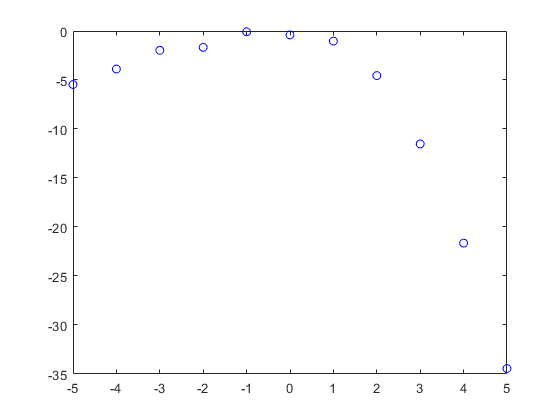

clc;
clear;

dane = [-5 -5.4606;-4 -3.8804;-3 -1.9699;-2 -1.6666;-1 -0.0764;0 -0.3971;1 -1.0303;2 -4.5483;3 -11.528;4 -21.6417;5 -34.4458];
plot(dane(:,1),dane(:,2),'bo')

wyswietlenie bledow

% blad_res_a

**funkcje pomocnicze**

algorytm obliczania wartosci wlasnych metoda QR bez przesuniec

function A = qr_bezprzesuniec(A)
    while tolerancja(A) > 0.00001
        [Q R] = qr_rozklad(A);
        A = R * Q;
    end
    A = wektor(A);
end

algorytm obliczania wartosci wlasnych metoda QR z przesunieciami

function qrp = qr_przesuniecia(A)
    qrp = 0;
end

rozklad QR

function [Q R] = qr_rozklad(A)
     rozmiar = size(A);
     Q = zeros(rozmiar);
     R = eye(rozmiar);
    %Gram-Schmidt
     for i = 1:rozmiar
         Q(:,i) = A(:,i);
         for j = 1:(i-1)
             R(j,i) = mydot(Q(:,j),A(:,i))/mydot(Q(:,j),Q(:,j));
             Q(:,i) = Q(:,i) - R(j,i)*Q(:,j);
         end
     end
    %normalizacja
     N = zeros(rozmiar);
     for i = 1:rozmiar
         N(i,i) = norm(Q(:,i));
         Q(:,i) = Q(:,i)/N(i,i);
     end
     R = N*R;
end

autorska implementacja matlabowej funkcji dot()

function md = mydot(A,B)
    rozmiar = size(A);
    md = 0;
    for i = 1:rozmiar
        md = md + A(i)*B(i);
    end
end

funkcja wektoryzujaca macierz diagonalna

function w = wektor(A)
    rozmiar = size(A);
    for i = 1:rozmiar
        w(i,1) = A(i,i);
    end
end

sprawdzenie tolerancji

function tol = tolerancja(A)
    rozmiar = size(A);
    A = abs(A);
    tol = 0;
    for i = 1:rozmiar
        if max(A(i,i+1:end)) > tol
            tol = max(A(i,i+1:end));
        end
        if max(A(i,1:i-1)) > tol
            tol = max(A(i,1:i-1));
        end
    end
end

tworzenie macierzy symetrycznej o zadanym rozmiarze

function mac_sym = macierz_symetryczna(rozmiar)
    mac_sym = randi([0 50],rozmiar,rozmiar);
    mac_sym = mac_sym + mac_sym';
end

tworzenie macierzy niesymetrycznej o zadanym rozmiarze

function mac_nsym = macierz_niesymetryczna(rozmiar)
    mac_nsym = randi([0 100],rozmiar,rozmiar);
end

norma residuum

function nr = norma_residuum(wspolczynniki, x, rozw)
    residuum = wspolczynniki*x - rozw;
    nr = norm(residuum);
end
